# PhysicalPendulumAnalysis

Analysis of lecture/demo physical pendulum motion, a swinging 65-inch-long rectangular steel bar, with an iPhone 7 affixed to its swinging end. Data collected with Sensorlog, 100 Hz, ~150 seconds so about 15,000 measurements of 3-axis accelerometer and 3-axis gyro sensor readings. Sensorlog app provides **EVERYTHING** available from a phone so the data import step provides additional corrected motion data.

 Author Duncan Carlsmith 

### Import data from text file.

Script for importing SensorLog data from the following text file:

`  LectureDemoPendulummy_iOS_device_2017-11-17_14-28-53_-0600.csv`

The import script was generated by using the [MATLAB import tool](https://www.mathworks.com/help/matlab/import_export/import-data-interactively.html) interactively to customize an import, and then exporting from the import tool the interactive work as a script. The data was imported with a comma as delimiter as column vectors with the first row of column vector labels used as vector names. The import script sets up options then uses [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html)  to read in the data into a table structure. It then uses table.thing notation to access the table to create vectors, one per column of data.

Set a flag in case the user wants to skip the import part as it can sometimes take a while and there is no need if the data is already in the workspace and one wants to add a plot here and there and rerun, skipping the import to save time.

myread=1;
if myread==1

Setup the Import Options and import the data.

opts = delimitedTextImportOptions("NumVariables", 72);


Specify range and delimiter, a comma for csv files.

opts.DataLines = [2, Inf];
opts.Delimiter = ",";


Specify column names and types

opts.VariableNames = ["loggingTimetxt", "loggingSampleN", "identifierForVendortxt", "deviceIDtxt", "locationTimestamp_since1970s", "locationLatitudeWGS84", "locationLongitudeWGS84", "locationAltitudem", "locationSpeedms", "locationCourse", "locationVerticalAccuracym", "locationHorizontalAccuracym", "locationFloorZ", "locationHeadingTimestamp_since1970s", "locationHeadingXT", "locationHeadingYT", "locationHeadingZT", "locationTrueHeading", "locationMagneticHeading", "locationHeadingAccuracy", "accelerometerTimestamp_sinceReboots", "accelerometerAccelerationXG", "accelerometerAccelerationYG", "accelerometerAccelerationZG", "gyroTimestamp_sinceReboots", "gyroRotationXrads", "gyroRotationYrads", "gyroRotationZrads", "motionTimestamp_sinceReboots", "motionYawrad", "motionRollrad", "motionPitchrad", "motionRotationRateXrads", "motionRotationRateYrads", "motionRotationRateZrads", "motionUserAccelerationXG", "motionUserAccelerationYG", "motionUserAccelerationZG", "motionAttitudeReferenceFrametxt", "motionQuaternionXR", "motionQuaternionYR", "motionQuaternionZR", "motionQuaternionWR", "motionGravityXG", "motionGravityYG", "motionGravityZG", "motionMagneticFieldXT", "motionMagneticFieldYT", "motionMagneticFieldZT", "motionMagneticFieldCalibrationAccuracyZ", "activityTimestamp_sinceReboots", "activitytxt", "activityActivityConfidenceZ", "activityActivityStartDatetxt", "pedometerStartDatetxt", "pedometerNumberofStepsN", "pedometerDistancem", "pedometerFloorAscendedN", "pedometerFloorDescendedN", "pedometerEndDatetxt", "altimeterTimestamp_sinceReboots", "altimeterResetbool", "altimeterRelativeAltitudem", "altimeterPressurekPa", "IP_en0txt", "IP_pdp_ip0txt", "deviceOrientationZ", "batteryStateR", "batteryLevelZ", "avAudioRecorderPeakPowerdB", "avAudioRecorderAveragePowerdB", "stateN"];
opts.VariableTypes = ["string", "double", "categorical", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "double", "categorical", "categorical", "double", "double", "double", "double", "categorical", "double", "double", "double", "double", "categorical", "categorical", "double", "double", "double", "double", "double", "double"];


Specify file level properties

opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";


Specify variable properties

opts = setvaropts(opts, "loggingTimetxt", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["loggingTimetxt", "identifierForVendortxt", "deviceIDtxt", "motionAttitudeReferenceFrametxt", "activitytxt", "activityActivityStartDatetxt", "pedometerStartDatetxt", "pedometerEndDatetxt", "IP_en0txt", "IP_pdp_ip0txt"], "EmptyFieldRule", "auto");


Import the data

tbl = readtable("/Users/duncancarlsmith/Documents/MATLAB/SensorKinetics/LectureDemoPendulummy_iOS_device_2017-11-17_14-28-53_-0600.csv", opts);

Convert to output type - vectors.

loggingTimetxt = tbl.loggingTimetxt;
loggingSampleN = tbl.loggingSampleN;
identifierForVendortxt = tbl.identifierForVendortxt;
deviceIDtxt = tbl.deviceIDtxt;
locationTimestamp_since1970s = tbl.locationTimestamp_since1970s;
locationLatitudeWGS84 = tbl.locationLatitudeWGS84;
locationLongitudeWGS84 = tbl.locationLongitudeWGS84;
locationAltitudem = tbl.locationAltitudem;
locationSpeedms = tbl.locationSpeedms;
locationCourse = tbl.locationCourse;
locationVerticalAccuracym = tbl.locationVerticalAccuracym;
locationHorizontalAccuracym = tbl.locationHorizontalAccuracym;
locationFloorZ = tbl.locationFloorZ;
locationHeadingTimestamp_since1970s = tbl.locationHeadingTimestamp_since1970s;
locationHeadingXT = tbl.locationHeadingXT;
locationHeadingYT = tbl.locationHeadingYT;
locationHeadingZT = tbl.locationHeadingZT;
locationTrueHeading = tbl.locationTrueHeading;
locationMagneticHeading = tbl.locationMagneticHeading;
locationHeadingAccuracy = tbl.locationHeadingAccuracy;
accelerometerTimestamp_sinceReboots = tbl.accelerometerTimestamp_sinceReboots;
accelerometerAccelerationXG = tbl.accelerometerAccelerationXG;
accelerometerAccelerationYG = tbl.accelerometerAccelerationYG;
accelerometerAccelerationZG = tbl.accelerometerAccelerationZG;
gyroTimestamp_sinceReboots = tbl.gyroTimestamp_sinceReboots;
gyroRotationXrads = tbl.gyroRotationXrads;
gyroRotationYrads = tbl.gyroRotationYrads;
gyroRotationZrads = tbl.gyroRotationZrads;
motionTimestamp_sinceReboots = tbl.motionTimestamp_sinceReboots;
motionYawrad = tbl.motionYawrad;
motionRollrad = tbl.motionRollrad;
motionPitchrad = tbl.motionPitchrad;
motionRotationRateXrads = tbl.motionRotationRateXrads;
motionRotationRateYrads = tbl.motionRotationRateYrads;
motionRotationRateZrads = tbl.motionRotationRateZrads;
motionUserAccelerationXG = tbl.motionUserAccelerationXG;
motionUserAccelerationYG = tbl.motionUserAccelerationYG;
motionUserAccelerationZG = tbl.motionUserAccelerationZG;
motionAttitudeReferenceFrametxt = tbl.motionAttitudeReferenceFrametxt;
motionQuaternionXR = tbl.motionQuaternionXR;
motionQuaternionYR = tbl.motionQuaternionYR;
motionQuaternionZR = tbl.motionQuaternionZR;
motionQuaternionWR = tbl.motionQuaternionWR;
motionGravityXG = tbl.motionGravityXG;
motionGravityYG = tbl.motionGravityYG;
motionGravityZG = tbl.motionGravityZG;
motionMagneticFieldXT = tbl.motionMagneticFieldXT;
motionMagneticFieldYT = tbl.motionMagneticFieldYT;
motionMagneticFieldZT = tbl.motionMagneticFieldZT;
motionMagneticFieldCalibrationAccuracyZ = tbl.motionMagneticFieldCalibrationAccuracyZ;
activityTimestamp_sinceReboots = tbl.activityTimestamp_sinceReboots;
activitytxt = tbl.activitytxt;
activityActivityConfidenceZ = tbl.activityActivityConfidenceZ;
activityActivityStartDatetxt = tbl.activityActivityStartDatetxt;
pedometerStartDatetxt = tbl.pedometerStartDatetxt;
pedometerNumberofStepsN = tbl.pedometerNumberofStepsN;
pedometerDistancem = tbl.pedometerDistancem;
pedometerFloorAscendedN = tbl.pedometerFloorAscendedN;
pedometerFloorDescendedN = tbl.pedometerFloorDescendedN;
pedometerEndDatetxt = tbl.pedometerEndDatetxt;
altimeterTimestamp_sinceReboots = tbl.altimeterTimestamp_sinceReboots;
altimeterResetbool = tbl.altimeterResetbool;
altimeterRelativeAltitudem = tbl.altimeterRelativeAltitudem;
altimeterPressurekPa = tbl.altimeterPressurekPa;
IP_en0txt = tbl.IP_en0txt;
IP_pdp_ip0txt = tbl.IP_pdp_ip0txt;
deviceOrientationZ = tbl.deviceOrientationZ;
batteryStateR = tbl.batteryStateR;
batteryLevelZ = tbl.batteryLevelZ;
avAudioRecorderPeakPowerdB = tbl.avAudioRecorderPeakPowerdB;
avAudioRecorderAveragePowerdB = tbl.avAudioRecorderAveragePowerdB;
stateN = tbl.stateN;

Clear temporary variables

clear opts tbl

Clear open figures if we are restarting this script. (Usefull if executing from the command line.)

delete(findall(0,'Type','figure'))

End the `if` for reading data.

end

Whew! Done.

**Try this:** Notice all the data. Many of these variables are a result of onboard data processing, eg. fusing accelerometer, gyro, and magnetometer data to get bearing. Notice you have access to GPS and to the footsteps taken... 

The [quaterions](https://en.wikipedia.org/wiki/Quaternion) might interest the math majors. Quaterions are  complex numbers on steroids and are useful for representing rotations.

**Start analysis by simply plotting the accelerometer and gyro data.**

Get read times since beginning of data for accelerometer, gyro, and motion variables. The read times for various variables are different because not all things are read or determined through calculation synchronously.

time  = accelerometerTimestamp_sinceReboots - accelerometerTimestamp_sinceReboots(1);
timew = gyroTimestamp_sinceReboots - gyroTimestamp_sinceReboots(1);
timem = motionTimestamp_sinceReboots - motionTimestamp_sinceReboots(1);

Let's shorten the variable names for raw accelerometer data.

ax = accelerometerAccelerationXG;
ay = accelerometerAccelerationYG;
az = accelerometerAccelerationZG;
atot=(ax.^2+ay.^2+az.^2).^(1/2); % magnitude of acceleration

Plot accelerometer data.

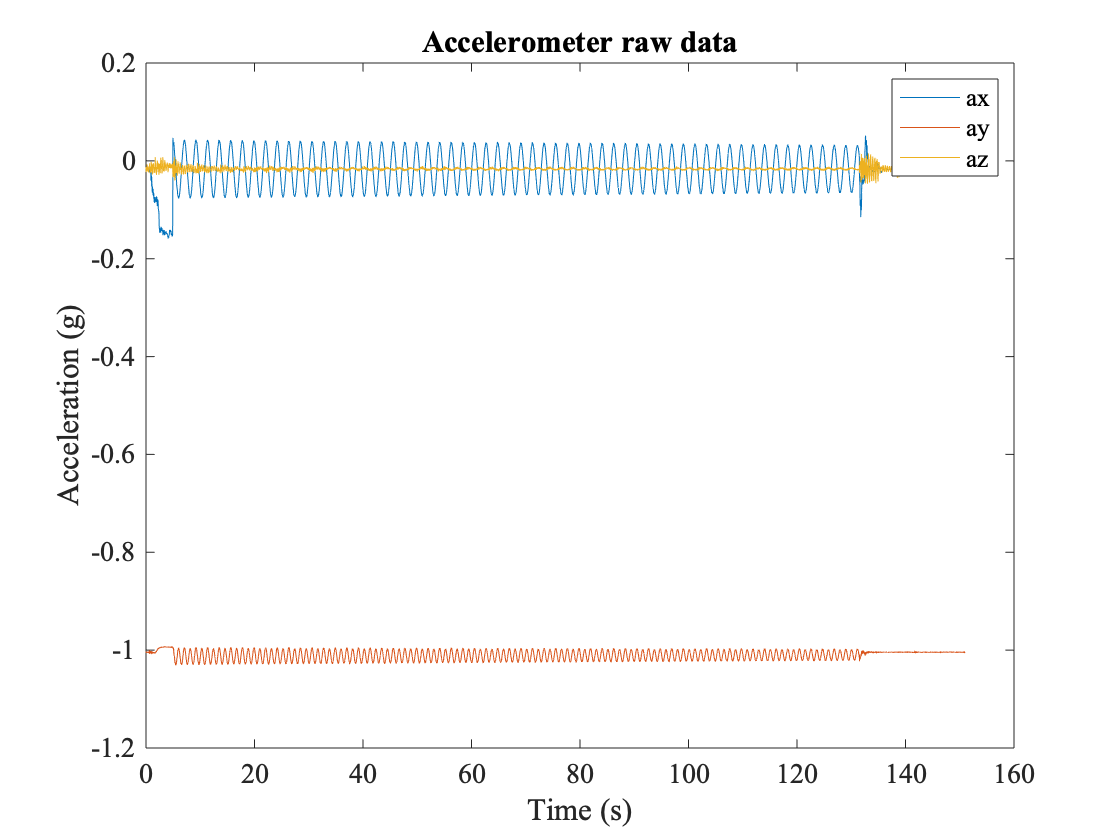

figure
plot(time, ax)
hold on
plot(time, ay)
plot(time, az)
%plot(time,atot);% Add this to the plot if you want to.
title('Accelerometer raw data')
xlabel('Time (s)')
ylabel('Acceleration (g)')
h=legend('ax','ay','az');

Very nice! The phone goes up and down (`a_y`) twice every period of the horizontal motion (`a_x`). The vertical acceleration `a_y` detects gravity all day, swinging or not, so appears offset by $g\simeq 9.8 ~{\rm m~s^{-2}}$. The acceleration normal to the face of the phone `a_z` should vanish, but, lo and behold, it doesn't because, um, it doesn't - the bar must swing back and forth a wee bit on the knife-edge.

Let's have a look at the gyro.

Make a figure for gyro data and reduced length variable names.

figure
wx=gyroRotationXrads;
wy=gyroRotationYrads;
wz=gyroRotationZrads;

Plot gyro data.

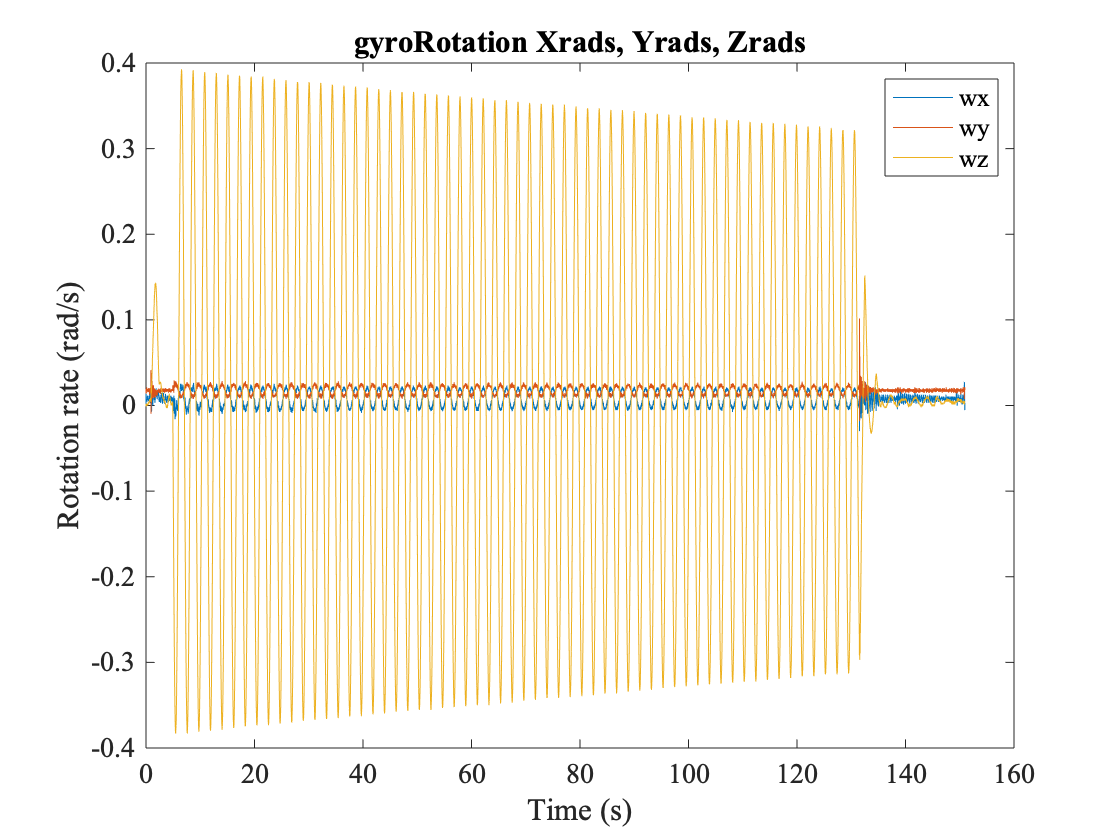

plot(timew, wx)
hold on
plot(timew, wy)
plot(timew, wz)
title('gyroRotation Xrads, Yrads, Zrads')
xlabel('Time (s)')
ylabel('Rotation rate (rad/s)')
h=legend('wx','wy','wz');

Plot motion rotation data which has drift removed. The raw data can sometimes suffer from sensor output drift (non-physical) and onboard processing/fusing remove this. That's a technical point...

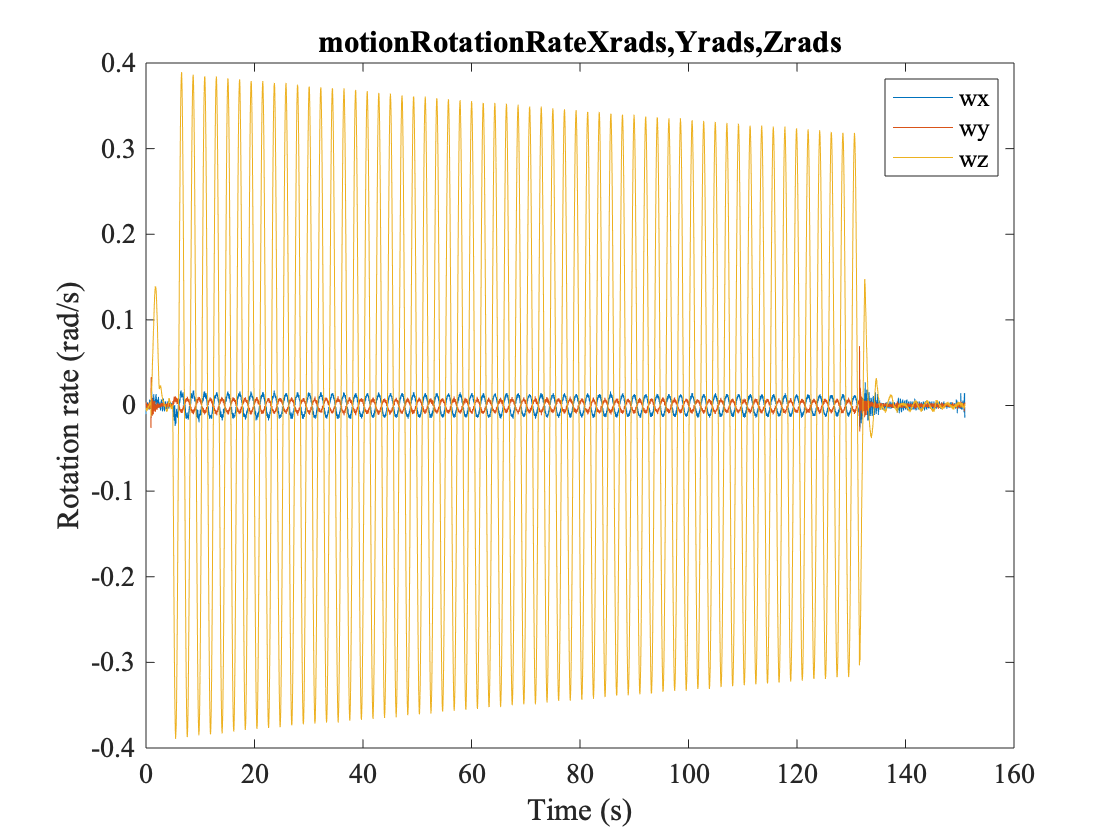

wx=motionRotationRateXrads;
wy=motionRotationRateYrads;
wz=motionRotationRateZrads;
figure
plot(timem,motionRotationRateXrads)
hold on
plot(timem,motionRotationRateYrads)
plot(timem,motionRotationRateZrads)
title('motionRotationRateXrads,Yrads,Zrads')
xlabel('Time (s)')
ylabel('Rotation rate (rad/s)')
h=legend('wx','wy','wz');

**Try this**: We could look at magnetometer and other things, but won't.... But the student can by selectively uncommenting bits of the following. I wonder what the magnetometer thinks of all this swinging around. Is the bar magnetized? Lot's of questions here...

% figure
% plot(timem,motionMagneticFieldXT)
% hold on
% plot(timem,motionMagneticFieldYT)
% plot(timem,motionMagneticFieldZT)
% title('motionMagneticFieldXT,YT,ZT')
% 
% figure
% plot(timem, motionUserAccelerationXG)
% hold on
% plot(timem, motionUserAccelerationYG)
% plot(timem, motionUserAccelerationZG)
% title('motionUserAccelerationXG,YG,ZG')
% 
% figure
% plot(timem,motionGravityXG)
% hold on
% plot(timem,motionGravityYG)
% plot(timem,motionGravityZG)
% title('motionGravityXG,YG,ZG')
% 
% figure
% plot(timem,motionYawrad)
% hold on
% plot(timem,motionRollrad)
% plot(timem,motionPitchrad)
% title('motionYawRad,RollRad,PitchRad')
% 
% figure
% plot(timem,motionQuaternionXR)
% hold on
% plot(timem,motionQuaternionYR)
% plot(timem,motionQuaternionZR)
% title('motionQuaternionXR,YR,ZR')
% 

**Try this**: Here's one way to integrate linear acceleration to get velocity. From that you can integrate velocity to get displacement. That means you can use the accelerometer to find your displacement - inertial navigation! The results are not so pretty for various reasons - that is a whole study to itself.  And one needs to compute and fuse with orientation information this translational information since the axes of the phone which define the translational information are themselves rotating with repect to an inertial frame of reference.

% t0=time(1);
% for i=1:length(time)
%     time(i)=time(i)-t0;
% end
% 
% vx=zeros(length(ax),1);
% vy=vx;
% vz=vx;
% for i=2: length(ax)
%     vx(i)=vx(i-1)+ax(i-1)*(time(i)-time(i-1));
%     vy(i)=vy(i-1)+ay(i-1)*(time(i)-time(i-1));
%     vz(i)=vz(i-1)+az(i-1)*(time(i)-time(i-1));
% end
% vy(length(ax))=vy(length(ax)-1);
% figure
% plot(time,vx)
% hold on
% plot(time,vy)
% plot(time,vz)
% title('vx,vy,vz vs time')

### Select the free motion portion of the data and analyze.

Change the following window limits to match your file. Pick start time to set phase assumed in model and end time defining free motion.

%tstart = 1.21; tend = 100;% start of time window for earlier file
tstart = 4.97-0.02;tend=131;% for 2017-11017_14-28-53

Create a vector of times between `tstart` and `tend`. The quantity `(time>tstart)&(time<tend)` is a vector of logicals specifying those indices for which the time is between the start and end values and t_win will be a reduced length vector containing only the times we wish to select.

t_win=time((time>tstart)&(time<tend));

Create corresponding linear acceleration vector components.

ax_win=ax((time>tstart)&(time<tend));
ay_win=ay((time>tstart)&(time<tend));
az_win=az((time>tstart)&(time<tend));

And windowed angular velocity vector components.

wt_win=time((timew>tstart)&(timew<tend));
wx_win=wx((timew>tstart)&(timew<tend));
wy_win=wy((timew>tstart)&(timew<tend));
wz_win=wz((timew>tstart)&(timew<tend));

Get the frequency spectra for linear and angular acceleration within the free motion time window. If a time series is represented as a sum of sine waves with various amplitudes, the frequency spectrum is the square of the amplitude (called power in the lingo) of the sine waves as a function of frequency.  We use the function [plomb](https://www.mathworks.com/help/signal/ref/plomb.html)  which works like a fast fourier transform but for time series data with irregular time spacing. (We can't count on the phone readout to proceed like clockwork.) The function receives the vector of values in the time series and a corresponding vector of times. We catch the power (squared amplitude of sine waves) as a vector and the corresponding frequencies as a vector.

[pxx_win,freq_win] = plomb(ax_win,t_win);
[pxy_win,freq_win] = plomb(ay_win,t_win);
[pxz_win,freq_win] = plomb(az_win,t_win);
[wxx_win,wfreq_win] = plomb(wx_win,wt_win);
[wxy_win,wfreq_win] = plomb(wy_win,wt_win);
[wxz_win,wfreq_win] = plomb(wz_win,wt_win);

**Try this**: Uncomment the following to plot the entire frequency spectrum.

% figure('Name','Frequency spectra acceleration (free motion)');
% semilogy(freq_win,pxx_win,'red')
% hold on
% semilogy(freq_win,pxy_win,'green')
% semilogy(freq_win,pxz_win,'blue')
% title('Frequency spectra acceleration (free motion)');
% h = legend('$a_x$','$a_y$','$a_z$');
% set(h,'interpreter','latex');
% xlabel('Frequency (Hz)');
% ylabel('Power spectral density');
% h = legend('$a_x$','$a_y$','$a_z$');

Plot the frequency spectra associated with linear acceleration for frequencies of interest, smaller than 5 Hz. We plot the power using [semilog](https://www.mathworks.com/help/matlab/ref/semilogx.html)  because the power ranges over several orders of magnitude.

figure('Name','Frequency spectra accleration(free motion)');
semilogy(freq_win(freq_win<5),pxx_win(freq_win<5),'red')
hold on
semilogy(freq_win(freq_win<5),pxy_win(freq_win<5),'green')
semilogy(freq_win(freq_win<5),pxz_win(freq_win<5),'blue')
title('Frequency spectra acceleration (free motion)');
h = legend('$a_x$','$a_y$','$a_z$');

One way to make a legend with special characters is ilustrated. MATLAB now actually simply recognizes LaTeX in labels without $-sign delimiters.

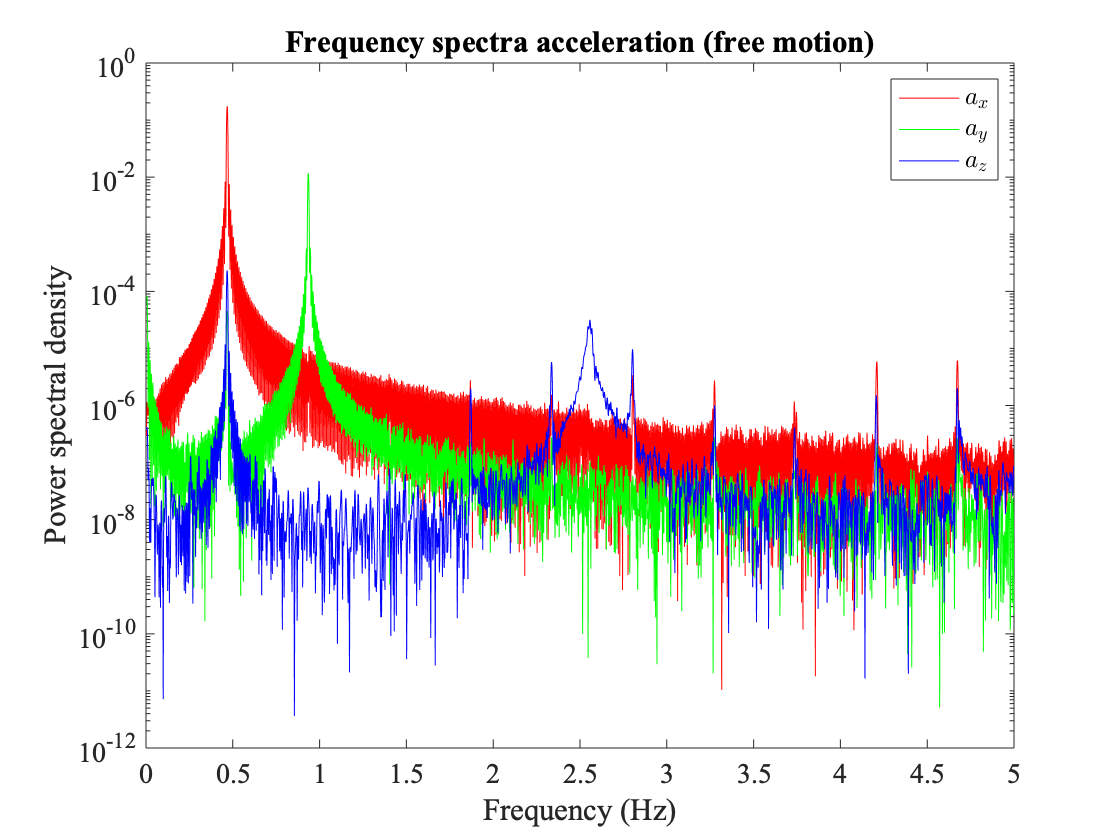

set(h,'interpreter','latex');
xlabel('Frequency (Hz)');
ylabel('Power spectral density');
h = legend('$a_x$','$a_y$','$a_z$');

Wow. Look how sharp those peaks are. One sees the swing in `a_x` data at about 0.5 Hz then the up-down at twice the frequency in the a_y data. The bar rocking frequency seen in a_z seems to be around 2.5 Hz. The rocking peak is relatively broad. That might be because rocking is not a simple harmonic motion, just similar to one.

Plot the frequency spectra for the gyro data.

**Try this**: To see the entire spectrum, uncomment the following.

% figure('Name','Frequency spectra gyro(free motion)');
% semilogy(wfreq_win,wxx_win,'red')
% hold on
% semilogy(wfreq_win,wxy_win,'green')
% semilogy(wfreq_win,wxz_win,'blue')
% title('Frequency spectra gyro(free motion)');
% h = legend('$w_x$','wa_y$','$w_z$');
% set(h,'interpreter','latex');
% xlabel('Frequency (Hz)');
% ylabel('Power spectral density');
% h = legend('$w_x$','$w_y$','$w_z$');

Plot the angular velocity frequency spectra for frequencies less than 5 Hz.

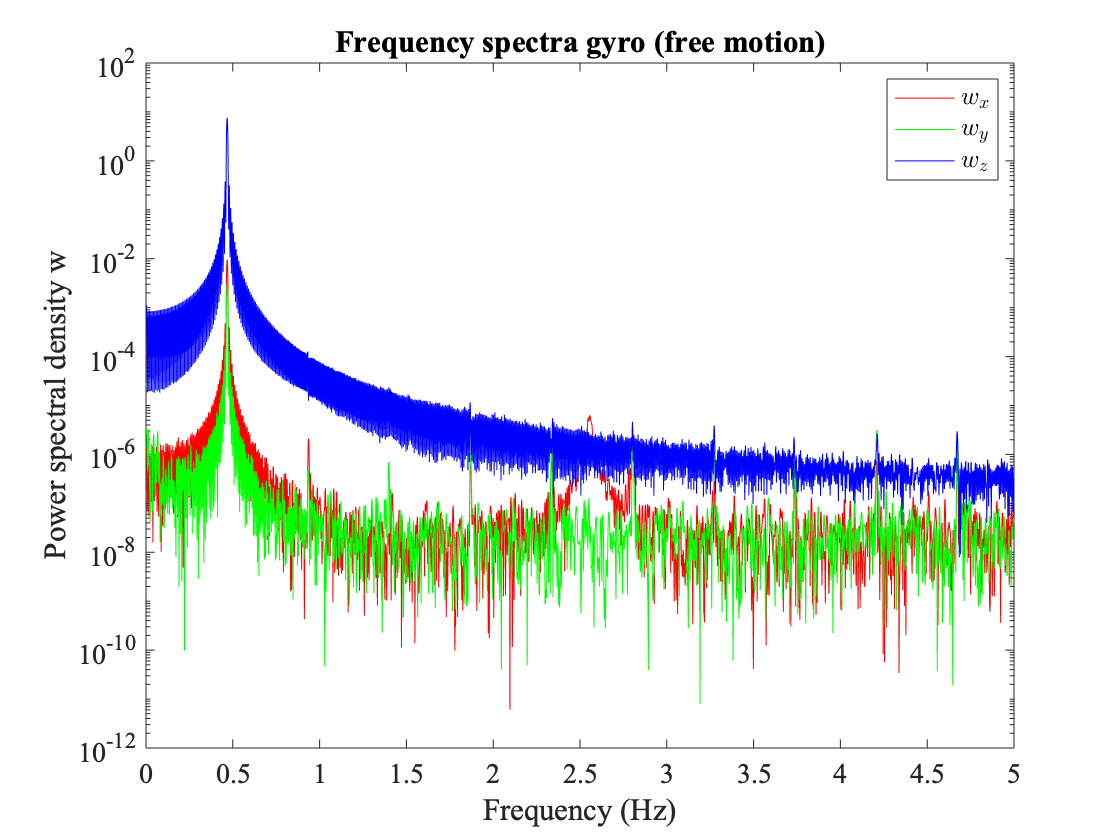

figure('Name','Frequency spectra gyro(free motion)');
semilogy(wfreq_win(wfreq_win<5),wxx_win(wfreq_win<5),'red')
hold on
semilogy(wfreq_win(wfreq_win<5),wxy_win(wfreq_win<5),'green')
semilogy(wfreq_win(wfreq_win<5),wxz_win(wfreq_win<5),'blue')
title('Frequency spectra gyro (free motion)');
h = legend('$w_x$','$w_y$','$w_z$');
set(h,'interpreter','latex');
xlabel('Frequency (Hz)');
ylabel('Power spectral density w');
h = legend('$w_x$','$w_y$','$w_z$');

These spectra are even cleaner. We see the swinging at around .5 Hz in all three components. The rocking about the knife edge shows up in the w_x at around 2.5 Hz because rocking is rotating the phone about its horizontal (mostly) axis. Right? That the peaks are so sharp is saying all of the motions are described by a few simple harmonic functions. There is very little noise/jitter.

## Create a rough model of these spectra more or less by hand and compare to the data. 

Take local acceleration of gravity from Google for Madison.

g=9.80562;%acceleration of gravity good to 0.002

Eyeball the max of plomb  x-acceleration frequency by zooming into that plot.

f=0.4675 ;

Compute the corresponding angular frequency.

omega0=2*pi*f; 

Estimate distance from knife edge support to inertial unit (IMU) within the phone as total length of bar minus distance to knife edge from the top end, less 1/4 the height of the phone.

R=(66.5-1.125-.25*(5+3/8))*.0254

R =        1.6264


Pick an initial release angle (not well measured) hand tuned to match amplitude of oscillation in the data. You could compute this/estimate this from the angular acceleration w_z amplitude using the expression $\omega_z(t)|_{\rm max} = \omega_0\phi_0\cos(\omega_0 )|_{\rm max} = \omega_0\phi_0$.

phi0= 8.65*0.0254/R

phi0 =       0.13509


It looks like the swinging is exponentially damped in time, i.e. has the form

$\theta(t) = \theta_0e^{-t/\tau}\cos(\omega_0 t+\phi)$. 

Estimate the damping time $\tau$ from a decrease in the peak amplitude and then tune it a bit.

tau = 100/.135;
tau=tau/1.03

tau =        719.17


THis time is long compared to the time of the observations and that makes sense - the amplitude decreases only 15% or so. Calculate a predicted amplitude at each (windowed) observed time.

theta0=phi0*exp(-(t_win)/tau);%initial angle * decay factor
theta0dot = -theta0/tau;

The phone sensor is close to but actually not on the axis of the bar. Estimate horizontal (x) offset of IMU (the sensor chip) from vertical when the bar and phone are in equilibrium based on iPhone tear down photos, and the offset (small) angle as the displacement distance divided by the distance of the phone from the knife-edge.

theta1 = 0.021/1.6;

Compute the angle of the IMU verus time using the exponentially damped amplitude. Here we are assuming tstart is a time when the amplitude is at a maximum.

theta = theta0.*cos(omega0*(t_win-tstart))+theta1;

Compute the derivative/angular acceleration during the window as well. Note that there are two time dependent factors (the exponential damping factor and the harmonic function) so we pick up two terms in the derivative so the angular frequency is not quite a damped simple harmonic.

thetadot = -omega0.*theta0.*sin(omega0*(t_win-tstart));
thetadot = thetadot-theta/tau;
thetaddot= -omega0^2*theta0.*cos(omega0*(t_win-tstart));
thetaddot= thetaddot +2*omega0.*sin(omega0*(t_win-tstart))/tau;
thetaddot = thetaddot +theta/tau^2;

The phone is itself probably cock-eyed relative to the bar by a small angle, and offset a smidge from the center of the bar so the phone reference frame vector components are rotated translated versions of those in the the bar frame. That means signals for nominal phone vertical/radial (y) axis and horizontal/azimuthal (x) axis are consequently mixed together. In particular, the vertical acceleration signal includes gravity as well as an updown oscillation at twice the natural frequency, a large number with a wiggle, and a small cock-eyed phone angle will feed a small part of that large number with a wiggle into the nominal horizontal signal, a small amplitude oscillation at the natural frequency. We can see in the data that something like that has happened.

The following corrects the prediction for this mixing.

sxx= -R*thetaddot-g*sin(theta); %propto R*theta0
syy=-R*thetadot.^2-g*cos(theta);%propto R*theta0^2 and dominated by g
% rotation of y-accelerometer re equilibrium vertical can mix signals
%phi=.024; 
phi=.0035; % hand tune this...

Compute the model signals by mixing radial and azimuthal components.

sx= cos(phi)*sxx+sin(phi)*syy;% give offset propto phi*g
sy=-sin(phi)*sxx+cos(phi)*syy;% adds to "radial" oscillation
offset = +1.00;% to fit radial and azimuthal on same plot
baseadjust=0.004;% used to offset drift/calibration error in az signal at rest

What about that rocking about the knife edge at 2.5 Hz? That complicates things but is small so let's ignore the rocking motion and move on.

OK. Make some plots comparing observed and predicted linear acceleration components. Subtract out the constant acceleration of gravity in the vertical component so the vertical and horizontal oscillatory components can be more easily compared. And normalize to units of g.

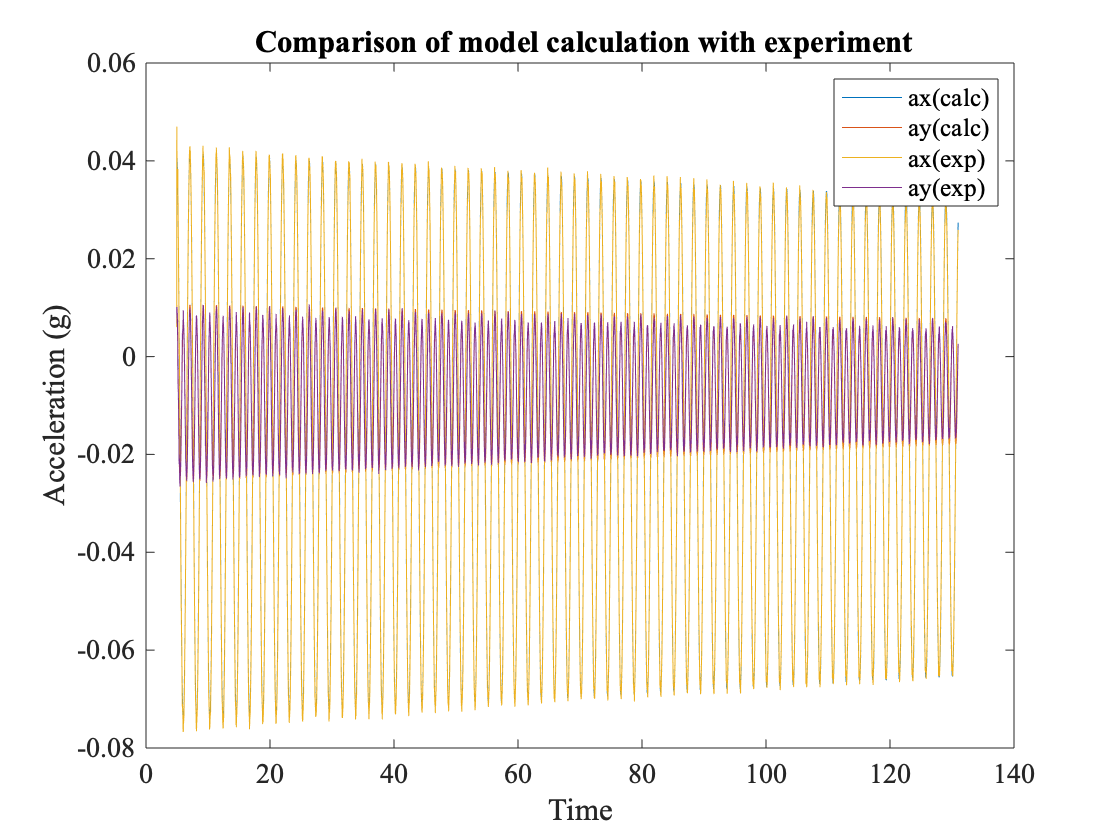

figure
plot(t_win, sx/g )% units are local g
hold on
plot(t_win, sy/g +offset)% units are local g
plot(t_win,ax_win*9.8/g)% units are local g
plot(t_win,ay_win*9.8/g+baseadjust+offset) %units are local g
xlabel('Time');
ylabel('Acceleration (g)');
title(' Comparison of model calculation with experiment');
h=legend('ax(calc)','ay(calc)','ax(exp)','ay(exp)');

The data and model agree so well, you can not see a difference at this scale. Let's plot the data over a smaller time range and see if we can detect any difference.

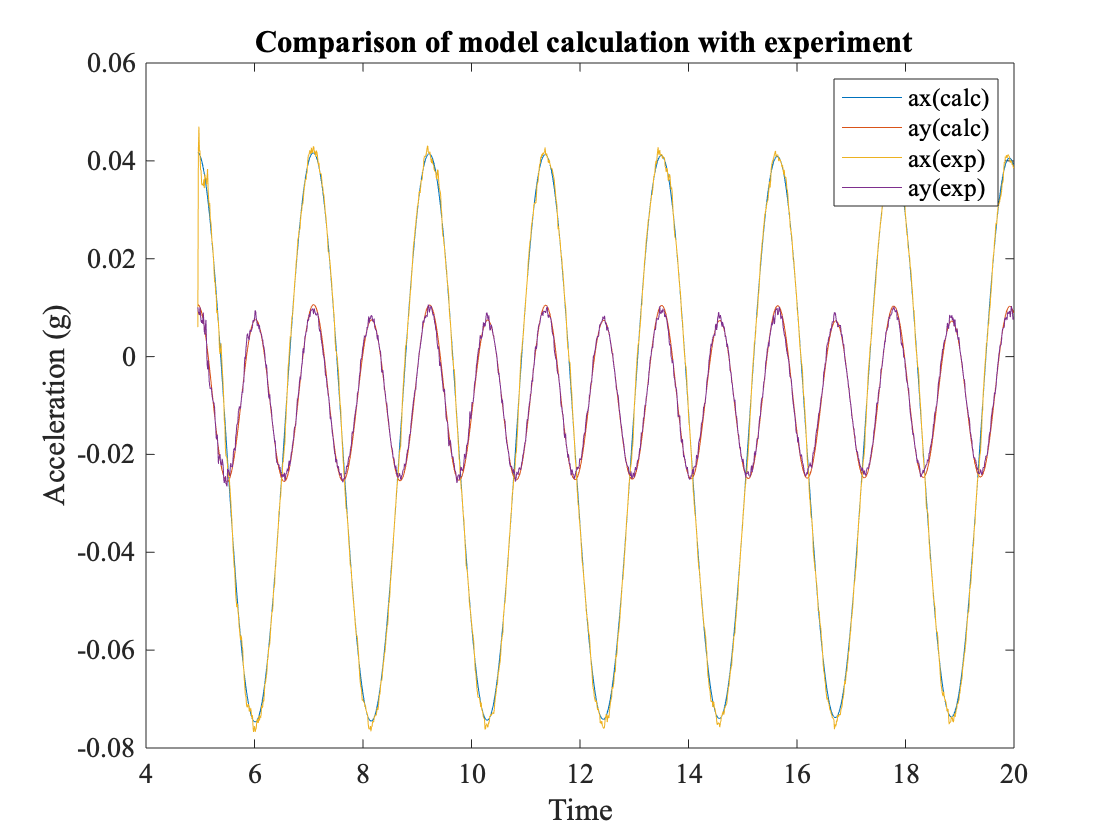

figure
plot(t_win(t_win<20), sx(t_win<20)/g )% units are local g
hold on
plot(t_win(t_win<20), sy(t_win<20)/g +offset)% units are local g
plot(t_win(t_win<20),ax_win(t_win<20)*9.8/g)% units are local g
plot(t_win(t_win<20),ay_win(t_win<20)*9.8/g+baseadjust+offset) %units oare local g
xlabel('Time');
ylabel('Acceleration (g)');
title(' Comparison of model calculation with experiment');
h=legend('ax(calc)','ay(calc)','ax(exp)','ay(exp)');

The data and calculation agree so well you can still barely tell the difference at this scale. 

**Try this**: Right near the peaks, you can see a little difference between the smooth curves and the slightly noisey data. If you zoom in on the this plot you can explore the differences.

Let's compare the data and prediction for the angular accelration data.

Calculate the angular acceleration z component using the model defined above.

wtstart=tstart;
thetaw = theta0.*cos(omega0*(wt_win-wtstart))+theta1;
thetadotw = -omega0.*theta0.*sin(omega0*(wt_win-wtstart));
thetadotw = thetadotw-thetaw/tau;

One can see in the angular velocity data small oscillations at the natural frequency in the x and y components. These could result from of order 1 degree misalignment of the IMU z-axis from the plane of oscillation. So include hand tuned small projections of z-component onto the x and y axes.

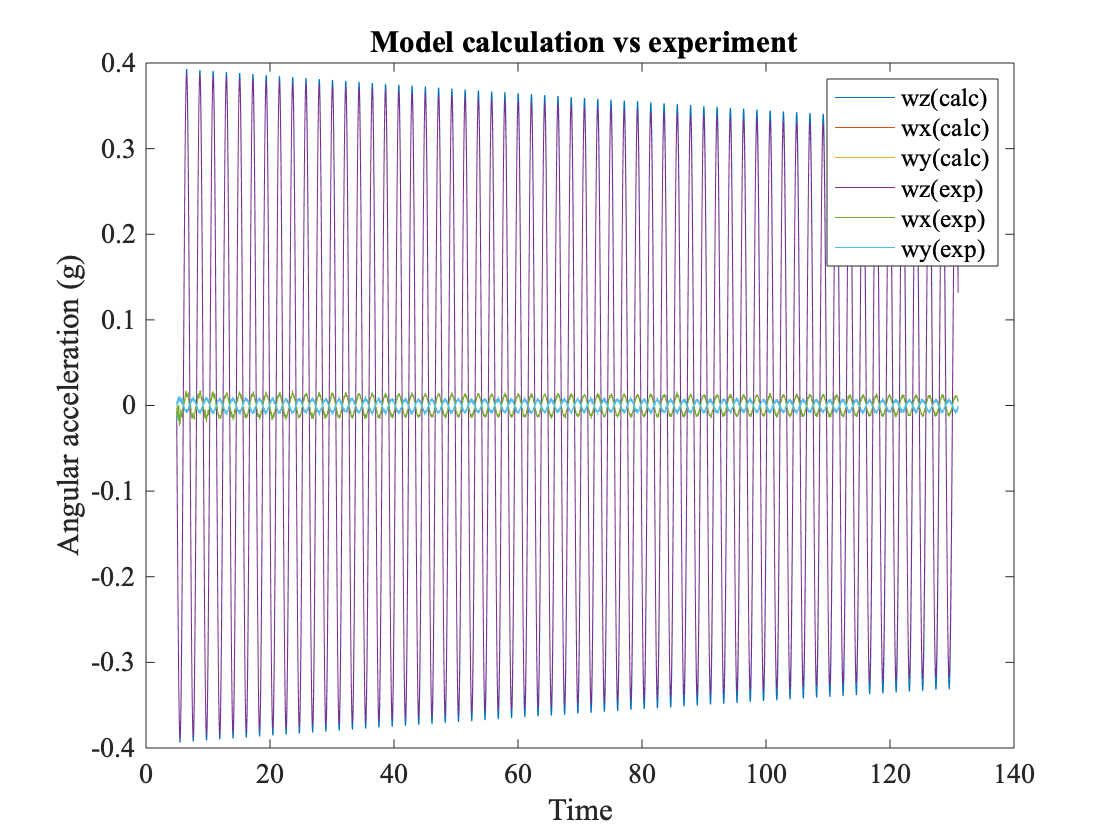

phi2=-.02;
phi3=.035;
wwz=cos(phi2)*thetadotw*cos(phi3);
wwx=sin(phi2)*thetadotw;
wwy=sin(phi3)*thetadotw;

figure
plot(wt_win, wwz )
hold on
plot(wt_win, wwx )
plot(wt_win, wwy )
hold on
plot(wt_win,wz_win)
plot(wt_win,wx_win)
plot(wt_win,wy_win)
xlabel('Time');
ylabel('Angular acceleration (g)');
title(' Model calculation vs experiment');
h=legend('wz(calc)','wx(calc)','wy(calc)','wz(exp)','wx(exp)','wy(exp)');

The agreement models the data rather well! The decay is not quite right. Look at wz calculation versus experiment - the colors of the peaks are different in the overlay. Open the plot in a new window and zoom in to really see.

Let's repeat the plot but expand the scale horizontally (in time).

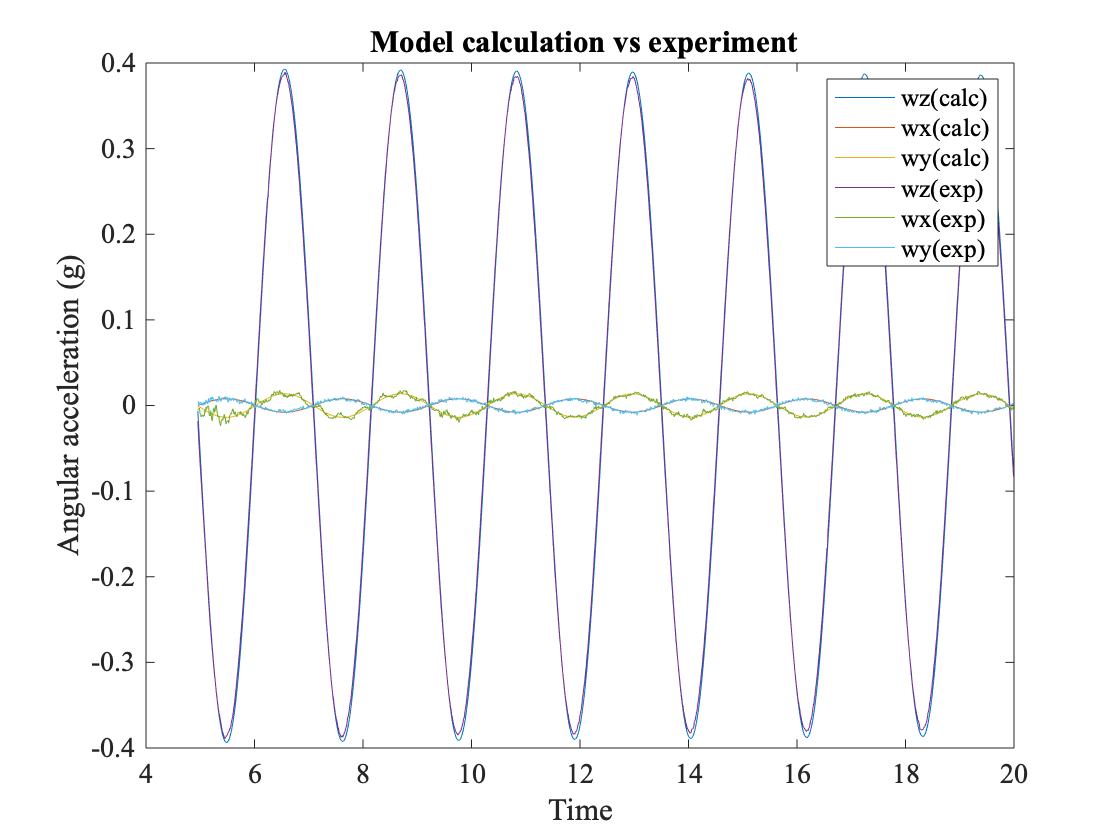

figure
plot(wt_win(t_win<20), wwz(t_win<20) )
hold on
plot(wt_win(t_win<20), wwx(t_win<20) )
plot(wt_win(t_win<20), wwy(t_win<20) )
hold on
plot(wt_win(t_win<20),wz_win(t_win<20))
plot(wt_win(t_win<20),wx_win(t_win<20))
plot(wt_win(t_win<20),wy_win(t_win<20))
xlabel('Time');
ylabel('Angular acceleration (g)');
title(' Model calculation vs experiment');
h=legend('wz(calc)','wx(calc)','wy(calc)','wz(exp)','wx(exp)','wy(exp)');

It is again very hard to see the difference between data and "theory" here without zooming in. You can see small differences between the curves and data in the z-component - the amplitude is a few percent off. The x and y components have been well reproduced assuming the z-axis of the IMU was not quite normal to the plane of oscillation. 

What we have suceeded in doing is empirically characterizing the decay of the oscillation over time, and have more or less accounted for the mixing of radial and angular components of acceleration in a frame of reference in which the bar is vertical in equilibrium when observed in the frame of the phone when it is not quite aligned with the bar.

This sure beats a lightgate measurement which provides but one measurement per perod of one position coordinate, a typical PASCO setup.

OK, let's try to fit the z-component of angular velocity data for the frequency, amplitude, and time constant assuming an exponentially damped oscillation. We have to use a nonlinear fit - the functional form is not linear in the parameters we fit for.

Define a model function for [nlinfit](https://www.mathworks.com/help/stats/nlinfit.html). b(1) is the amplitude, b(2) the time constant, b(3) the angular frequency, b(4) the initial phase of the oscillation.

modelfun = @(b,t)(( b(1)*exp(-t./b(2)).*cos(b(3).*t+b(4)) ));

Pick initial estimates for the parameters.

b0=[phi0;tau;omega0;0];

Set up the fitting and fit.

opts = statset('nlinfit');
[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(wt_win,wwz,modelfun,b0);

Print the parameter values and the errors.

beta

beta =       0.39649
       719.15
       2.9374
     -0.40244


sqrt(diag(CovB))

ans =    5.1152e-07
    0.0090292
   1.7511e-08
   1.2915e-06


Plot the data and fit.

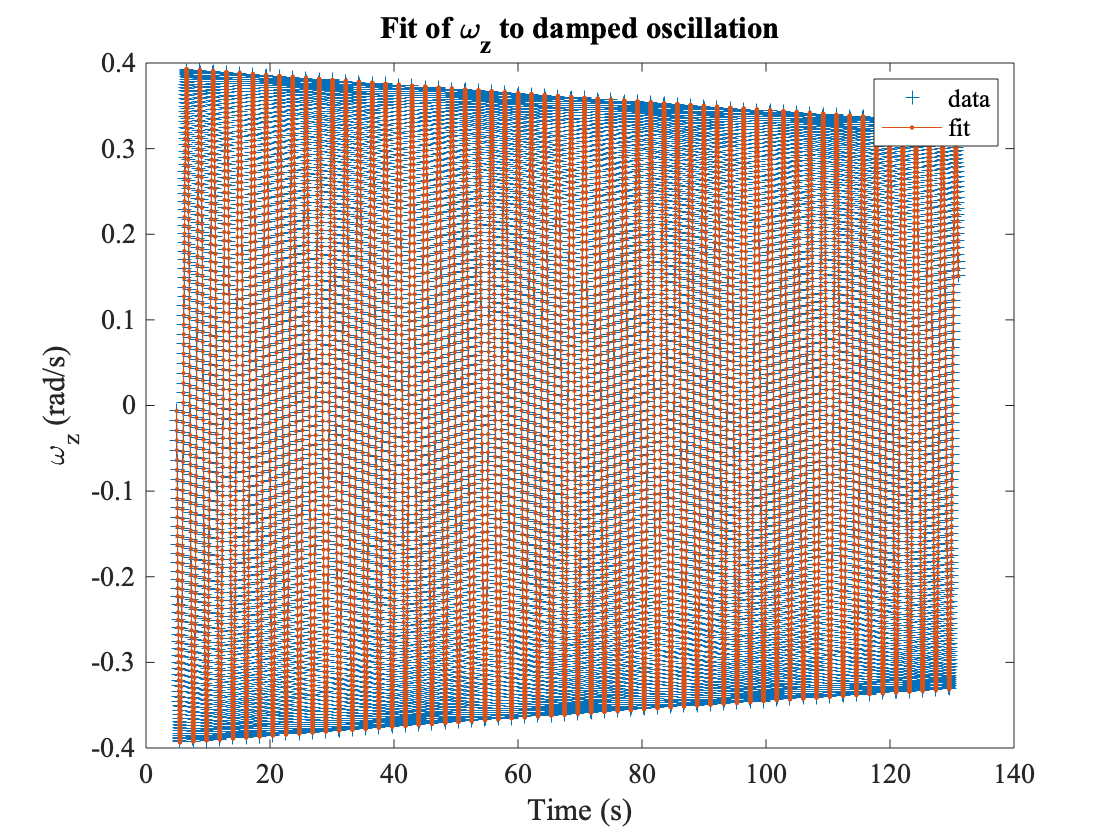

figure
plot(wt_win, wwz,'+' )
hold on
yfit=modelfun(beta,wt_win);
plot(wt_win,yfit,'.-')
title('Fit of \omega_z to damped oscillation')
xlabel('Time (s)');ylabel('\omega_z (rad/s)')
legend('data','fit')

You have to zoom in very far to see deviations between the data and the fit. Let's plot residuals.

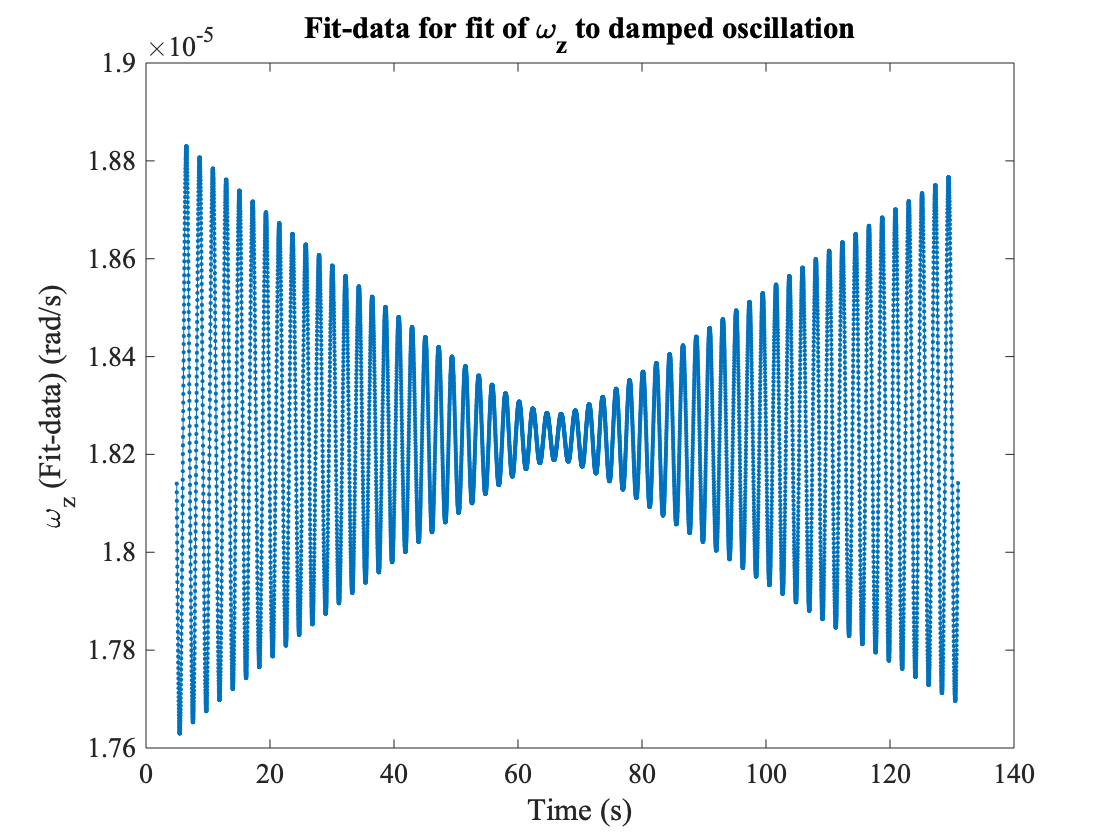

figure
plot(wt_win,(yfit-wwz),'.-')
title('Fit-data for fit of \omega_z to damped oscillation')
xlabel('Time (s)');ylabel('\omega_z (Fit-data) (rad/s)')

The maximum deviation is roughly $1.2\times 10^{-5}/.4\simeq 5\times 10^{-5}$ and clearly shows an interesting oscillatory pattern to be investigated. The residuals are not centered on zero. The fit is systematically high. This might be some offset in the angular velocity sensor reading. We could build a more elaborate model function...

The standard error on the frequency found by nlinfit assumes a random error equal to the rms of the final residuals:

rms(yfit-wwz)

ans =    1.8234e-05


There are 15,000-ish points and the fitter is estimating the error on the frequency to be of order 1e-8. Does that make sense? That question requires further consideration, and one must begin to wonder about the accuracy of the phone time readings.

Let's compare the fitted angular frequency to expectation for a bar.

L=(66.5-1.125)*0.0254;% length of bar from knife edge
g=9.81;% acceleration of gravity
omegapredicted= (3*g/(2*L))^(1/2)

omegapredicted =        2.9769


Compute the ratio of predicted angular frequency over measured angular frequency.

omegapredicted/beta(3)

ans =        1.0134


The observed frequency is about 1% lower than the prediction. But we neglected the mass above the knife-edge. If the moment of inertia about the knife edge of that mass were equal to that below the knife-edge, the entire bar could rotate freely so if the the mass above the knife edge is included the predicted frequency should be slightly smaller. That systematic correction could be calculated and estimated from the detailed geometry of the hole in the bar that accomodates the knife edge. 